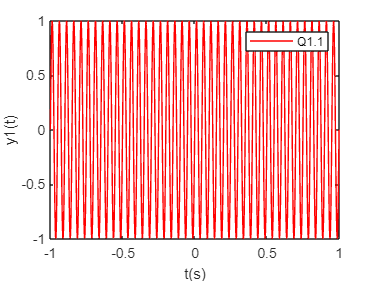

%Question 1 part 1
t = linspace(-1,1,1000);
a = 1 + mod(163,3);
y1 = sin(20*pi*a*t);
figure; plot(t,y1,'r')
xlabel('t(s)');
ylabel('y1(t)');
legend('Q1.1')

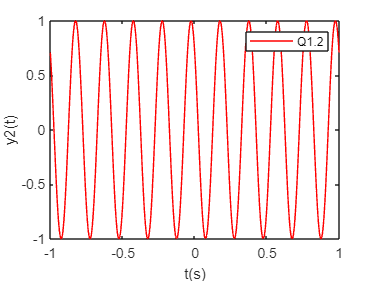

%Part 2
y2 = cos((5*pi*a*t) + (pi/4));
figure; plot(t, y2,'r')
xlabel('t(s)');
ylabel('y2(t)');
legend('Q1.2');

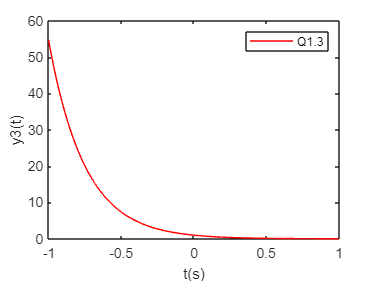

%Part 3
y3 = exp(-2*a*t);
figure; plot(t, y3,'r')
xlabel('t(s)');
ylabel('y3(t)');
legend('Q1.3');

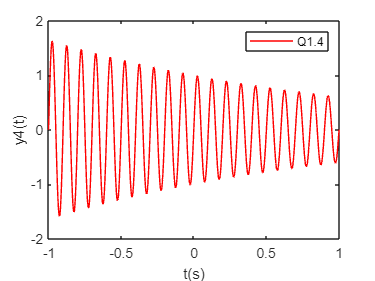

%Part 4
y4 = exp(-0.25*a*t).*sin(20*pi*t);
figure; plot(t, y4,'r')
xlabel('t(s)');
ylabel('y4(t)');
legend('Q1.4');

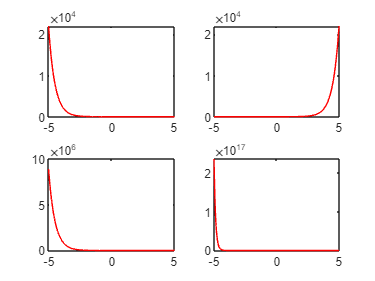

%Question 2
t = linspace(-5,5,100000);
    
subplot(2,2,1)
y1 = exp(-a*t);
plot(t, y1,'r')

subplot(2,2,2)
y2 = exp(a*t);
plot(t, y2,'r')

subplot(2,2,3)
y3 = exp(-a*(t-1.5*a));
plot(t, y3,'r')

subplot(2,2,4)
y4 = exp(-a*(2*a*t));
plot(t, y4,'r')

A=load('ECG_Data.txt');
y = size(A)

y =         6884           1


A(:,1)

ans =     0.2284
    0.2240
    0.2206
    0.2163
    0.2111
    0.2059
    0.1998
    0.1964
    0.1938
    0.1886


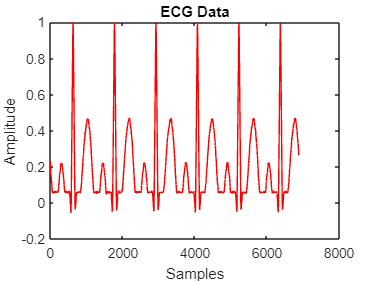

figure; plot(A(:,1),'r')
xlabel('Samples')
ylabel('Amplitude')
title('ECG Data')

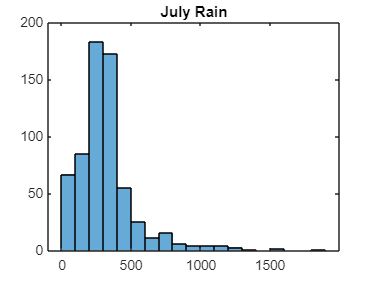

july = load('RainFallIndia_July.txt');
jan = load('RainFallIndia_Jan.txt');

figure; histogram(july(:,1))
title('July Rain')

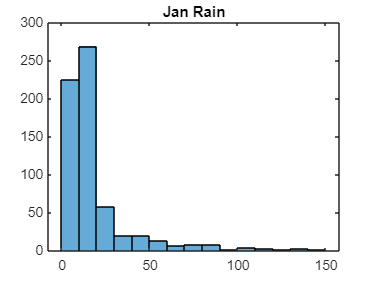

figure; histogram(jan(:,1))
title('Jan Rain')


mean(july(:,1))

ans = 326.0936

mean(jan(:,1))

ans = 18.3513


std(july(:,1))

ans = 221.5326

std(jan(:,1))

ans = 21.0991

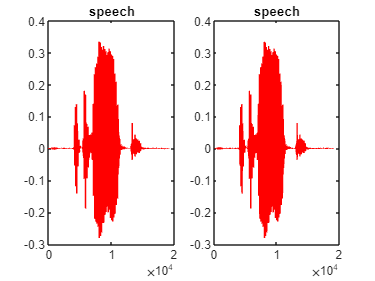

[s,Fs] = audioread('speech.wav');
sound(s,Fs)
F = 25000000 * a;
y = s*cos(2*pi*F/Fs);
sound(y,Fs);
subplot(1,2,1)
plot(s,'r')
title('speech')
subplot(1,2,2)
plot(y,'r')
title('speech')

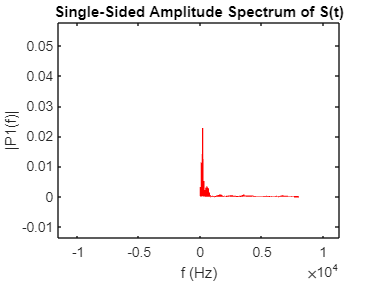


% Plotting the Fast Fourier Transform of the sound wave                 
T = 1/Fs;             % Sampling period       
L = 19120;             % Length of signal
t = (0:L-1)*T;        % Time vector

f = Fs*(0:(L/2))/L;

Y = fft(s);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

figure;
plot(f,P1,'r') 
title("Single-Sided Amplitude Spectrum of S(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

t = linspace(0,5,20000);
fs = 44100;
y1 =  sin(220*t);
sound(y1, fs);

y2 = sin(246.94*t);
sound(y2, fs);

y3 = sin(261.63*t);
sound(y3, fs);

y4 = sin(293.66*t);
sound(y4, fs);

y5 = sin(329.63 *t);
sound(y5, fs);

y6 = sin(349.23*t);
sound(y6, fs);

y7 = sin(392*t);
sound(y7, fs);

z = [y3 y4 y5 y6 y7 y1 y2];
audiowrite('sg1.wav', z, fs);

[s,Fs] = audioread('sg1.wav');
Fs;
z;
sound(s, Fs);

con = load('ConvFile1.txt');

Error using load
Unable to find file or directory 'ConvFile1.txt'.

[s,Fs] = audioread('Track001.wav');
res = conv2(s, con);
audiowrite('conv.wav', res, Fs);
sound(res, Fs);

